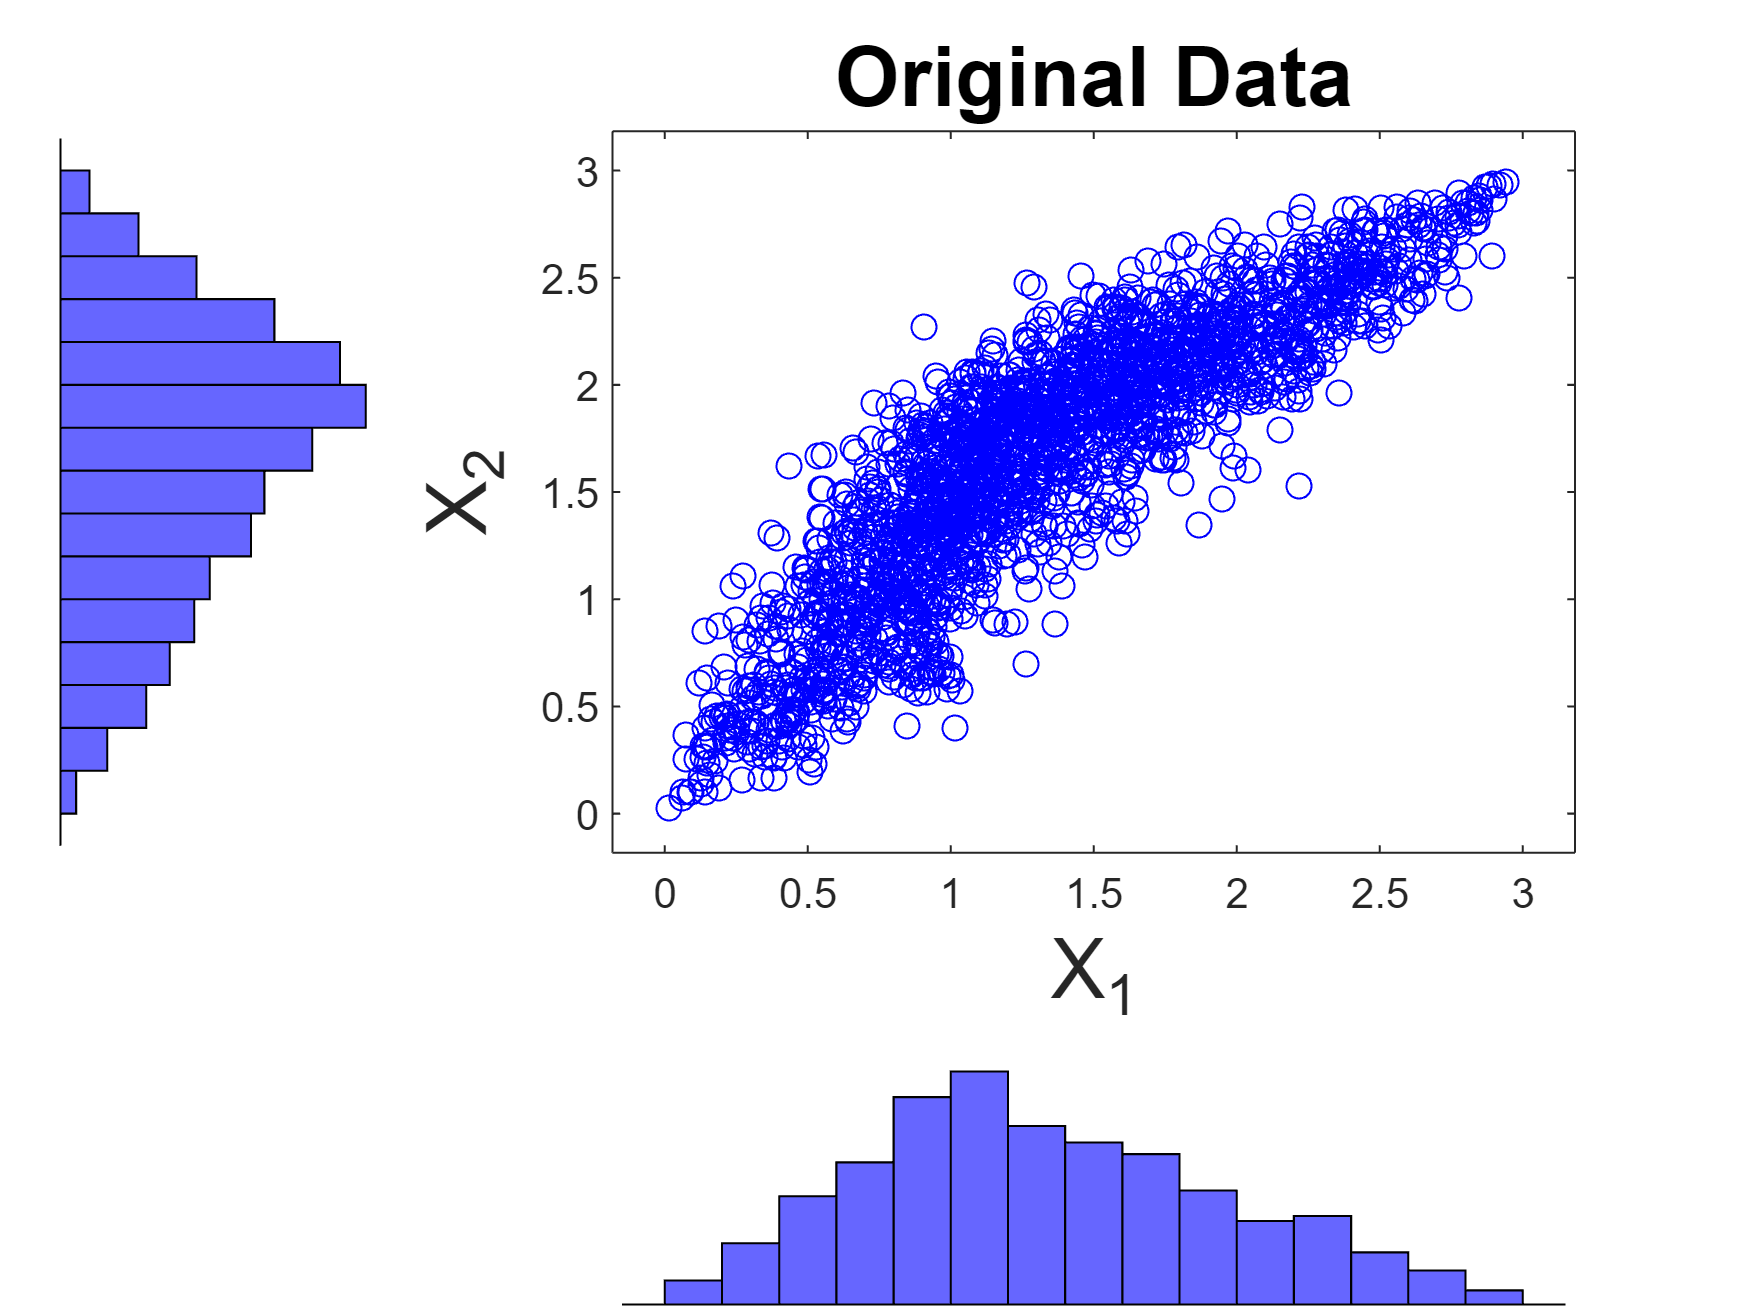

%% Triangular Distributions with Gaussian Copula
mypause=@()snapnow;

n=2000;
u=rand(n,2);
x=iccorrelate([triinv(u(:,1),0,1,3),triinv(u(:,2),0,2,3)],[1,.9;.9,1]);
scatterhist(x(:,1),x(:,2),'Color','b');
title('Original Data','FontSize',20)
xlabel('X_1','FontSize',20)
ylabel('X_2','FontSize',20)

mypause()
%% Triangular Distributions with Gaussian Copula: Indeed
z=norminv(uniformer(x));
h=scatterhist(z(:,1),z(:,2),'Color','b')

h =   1×3 Axes array:

    Axes    Axes    Axes


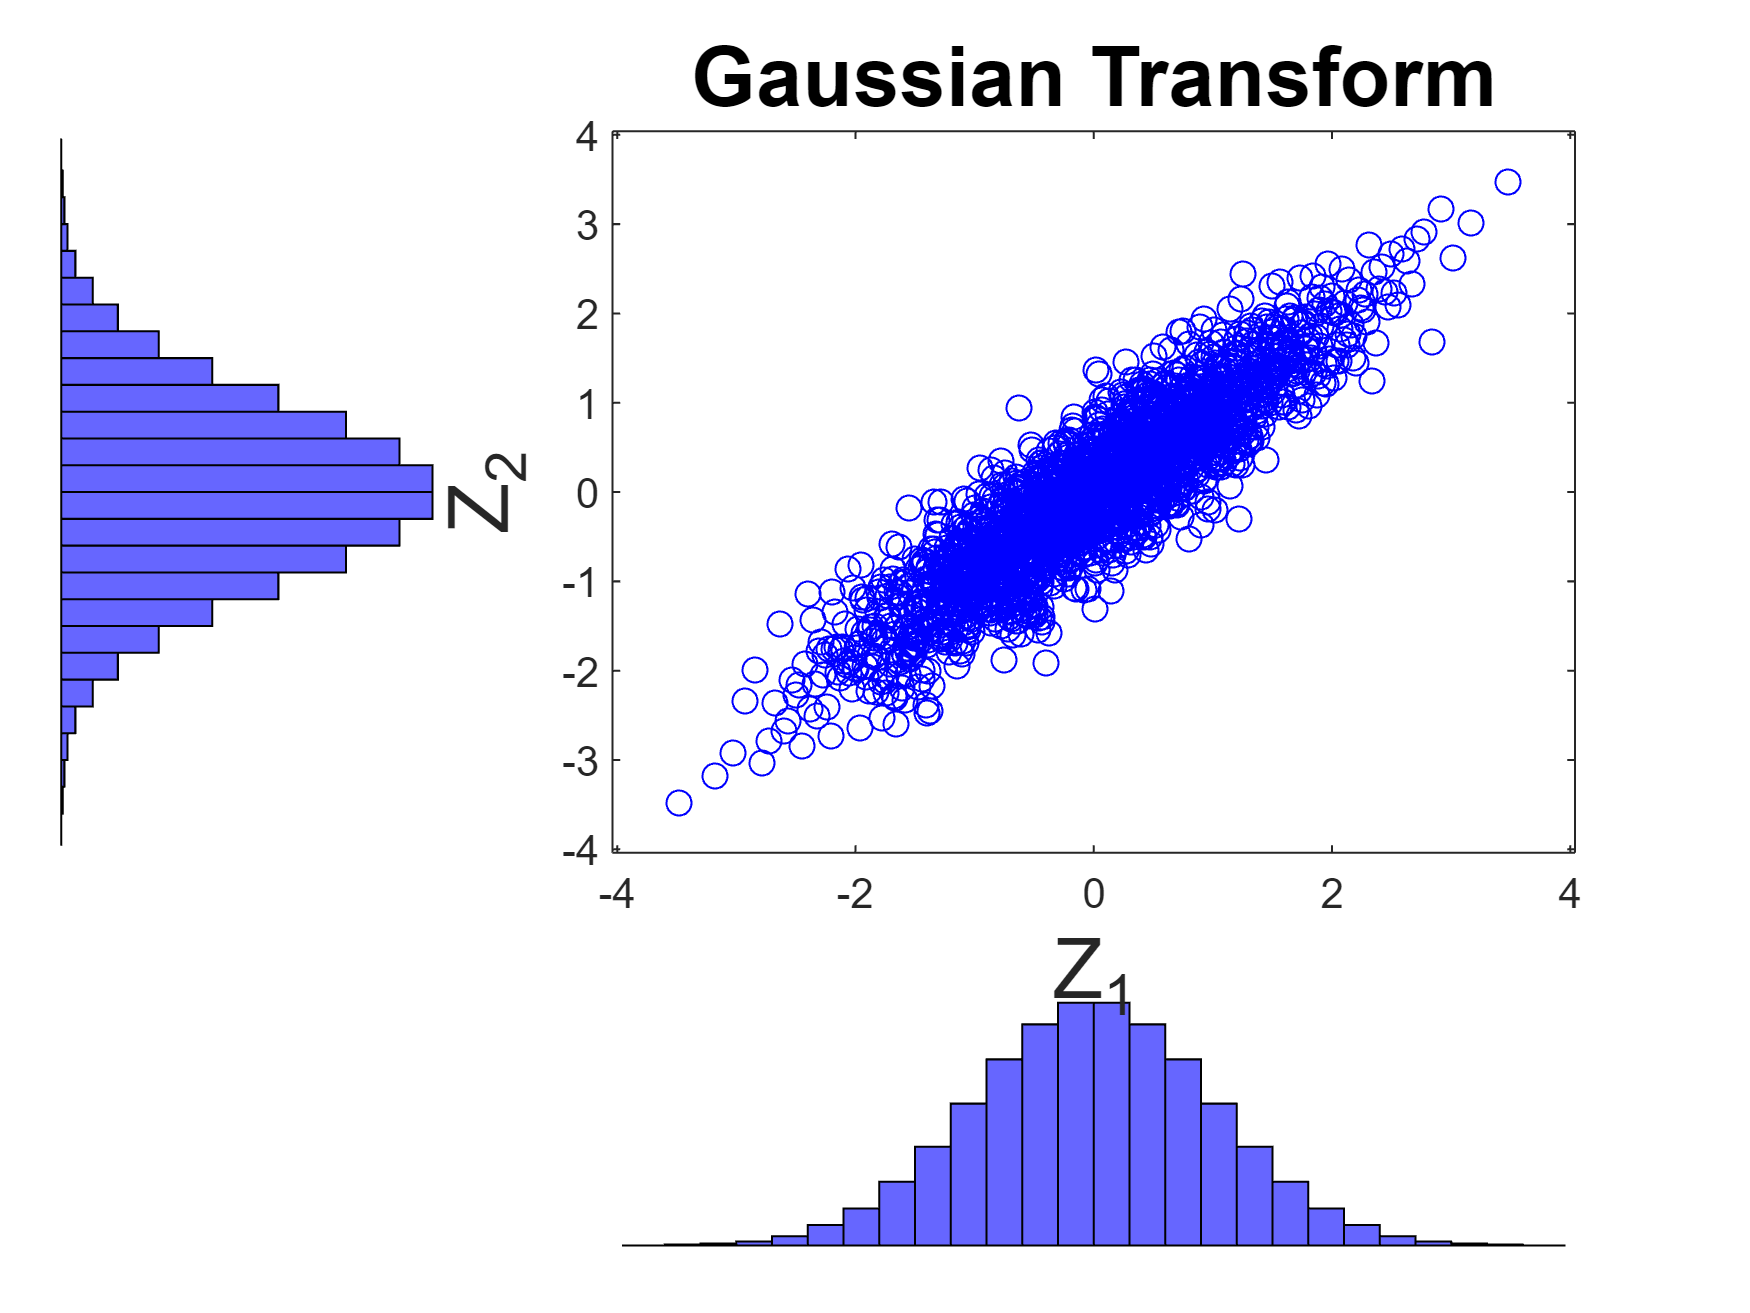

title('Gaussian Transform','FontSize',20)
xlabel('Z_1','FontSize',20)
ylabel('Z_2','FontSize',20)
axes(h(1))

%hold('on')
%plot([-3,3],[-3,+3]*.9,'r-','LineWidth',3)


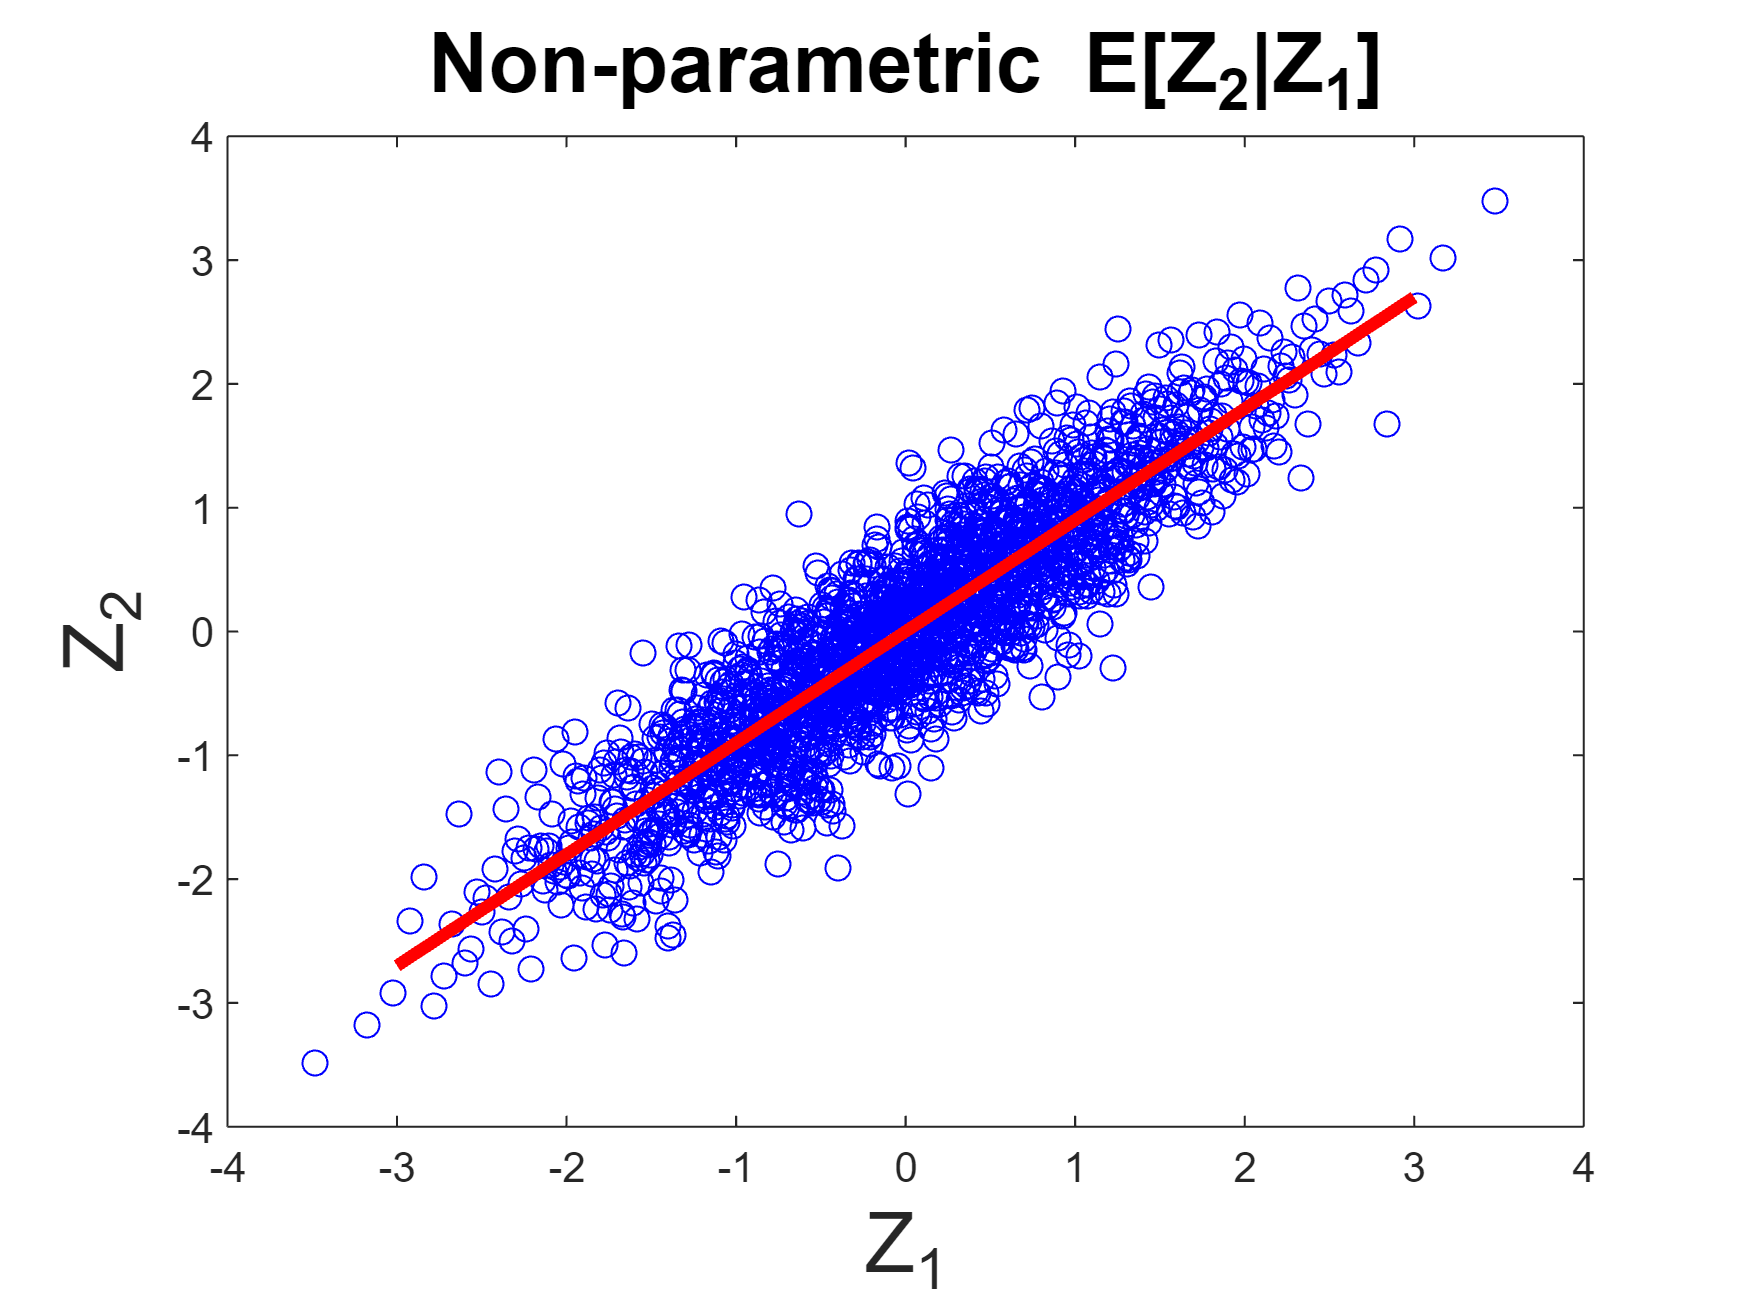

%% Remove Linear Trend, Permute, Add Trend
figure
%subplot(4,1,1)
plot(z(:,1),z(:,2),'bo');hold on; plot([-3,3],.9*[-3,3],'r-','LineWidth',3)
% axes 1
title('Non-parametric E[Z_{2}|Z_{1}]','FontSize',20)
xlabel("Z_1",'FontSize',20)
ylabel("Z_2",'FontSize',20)

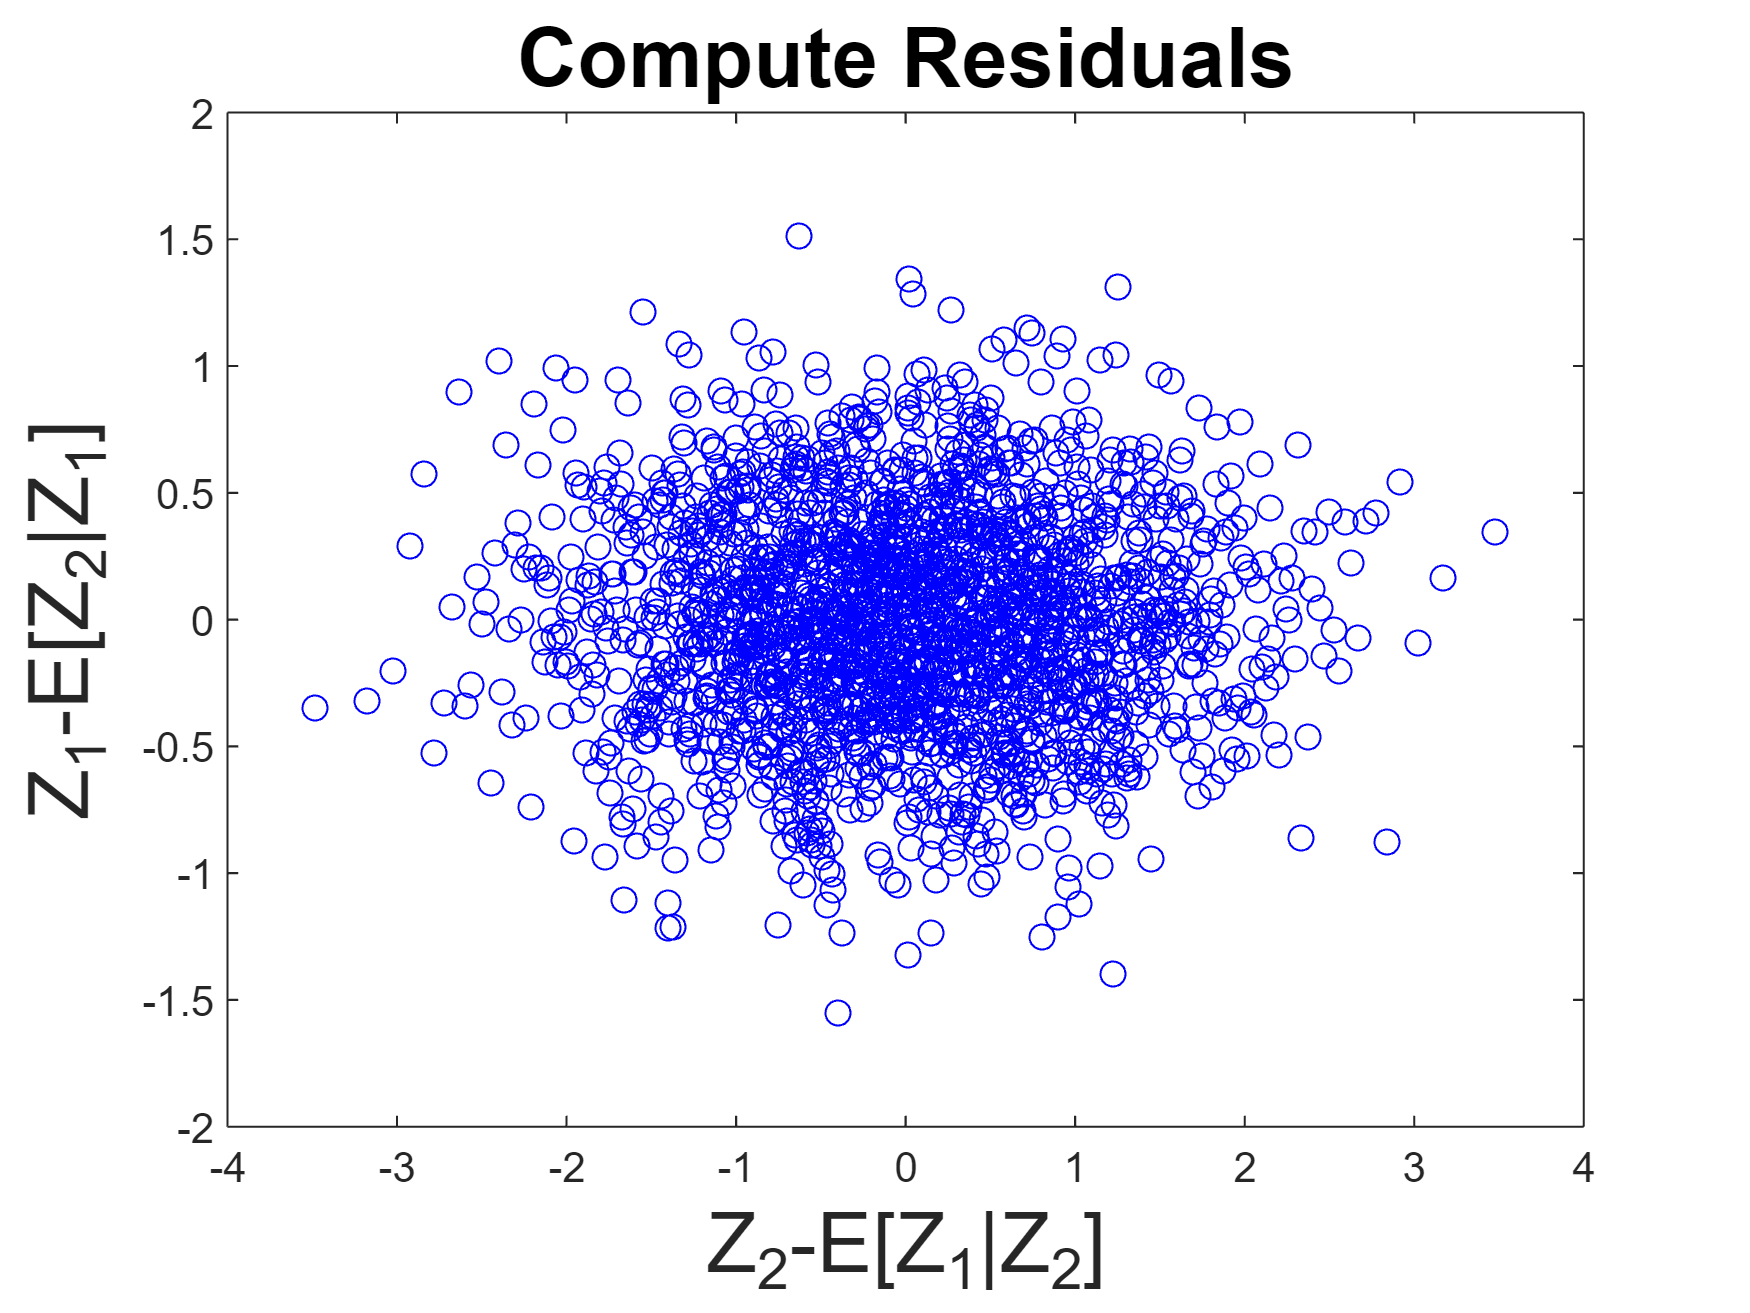


%subplot(4,1,2)
%%
w=z(:,2)-.9*z(:,1);
figure
plot(z(:,1),w,'bo')
m=w(randperm(length(w)));
title('Compute Residuals','FontSize',20)
xlabel('Z_{2}-E[Z_{1}|Z_{2}]','FontSize',20)
ylabel('Z_{1}-E[Z_{2}|Z_{1}]','FontSize',20)

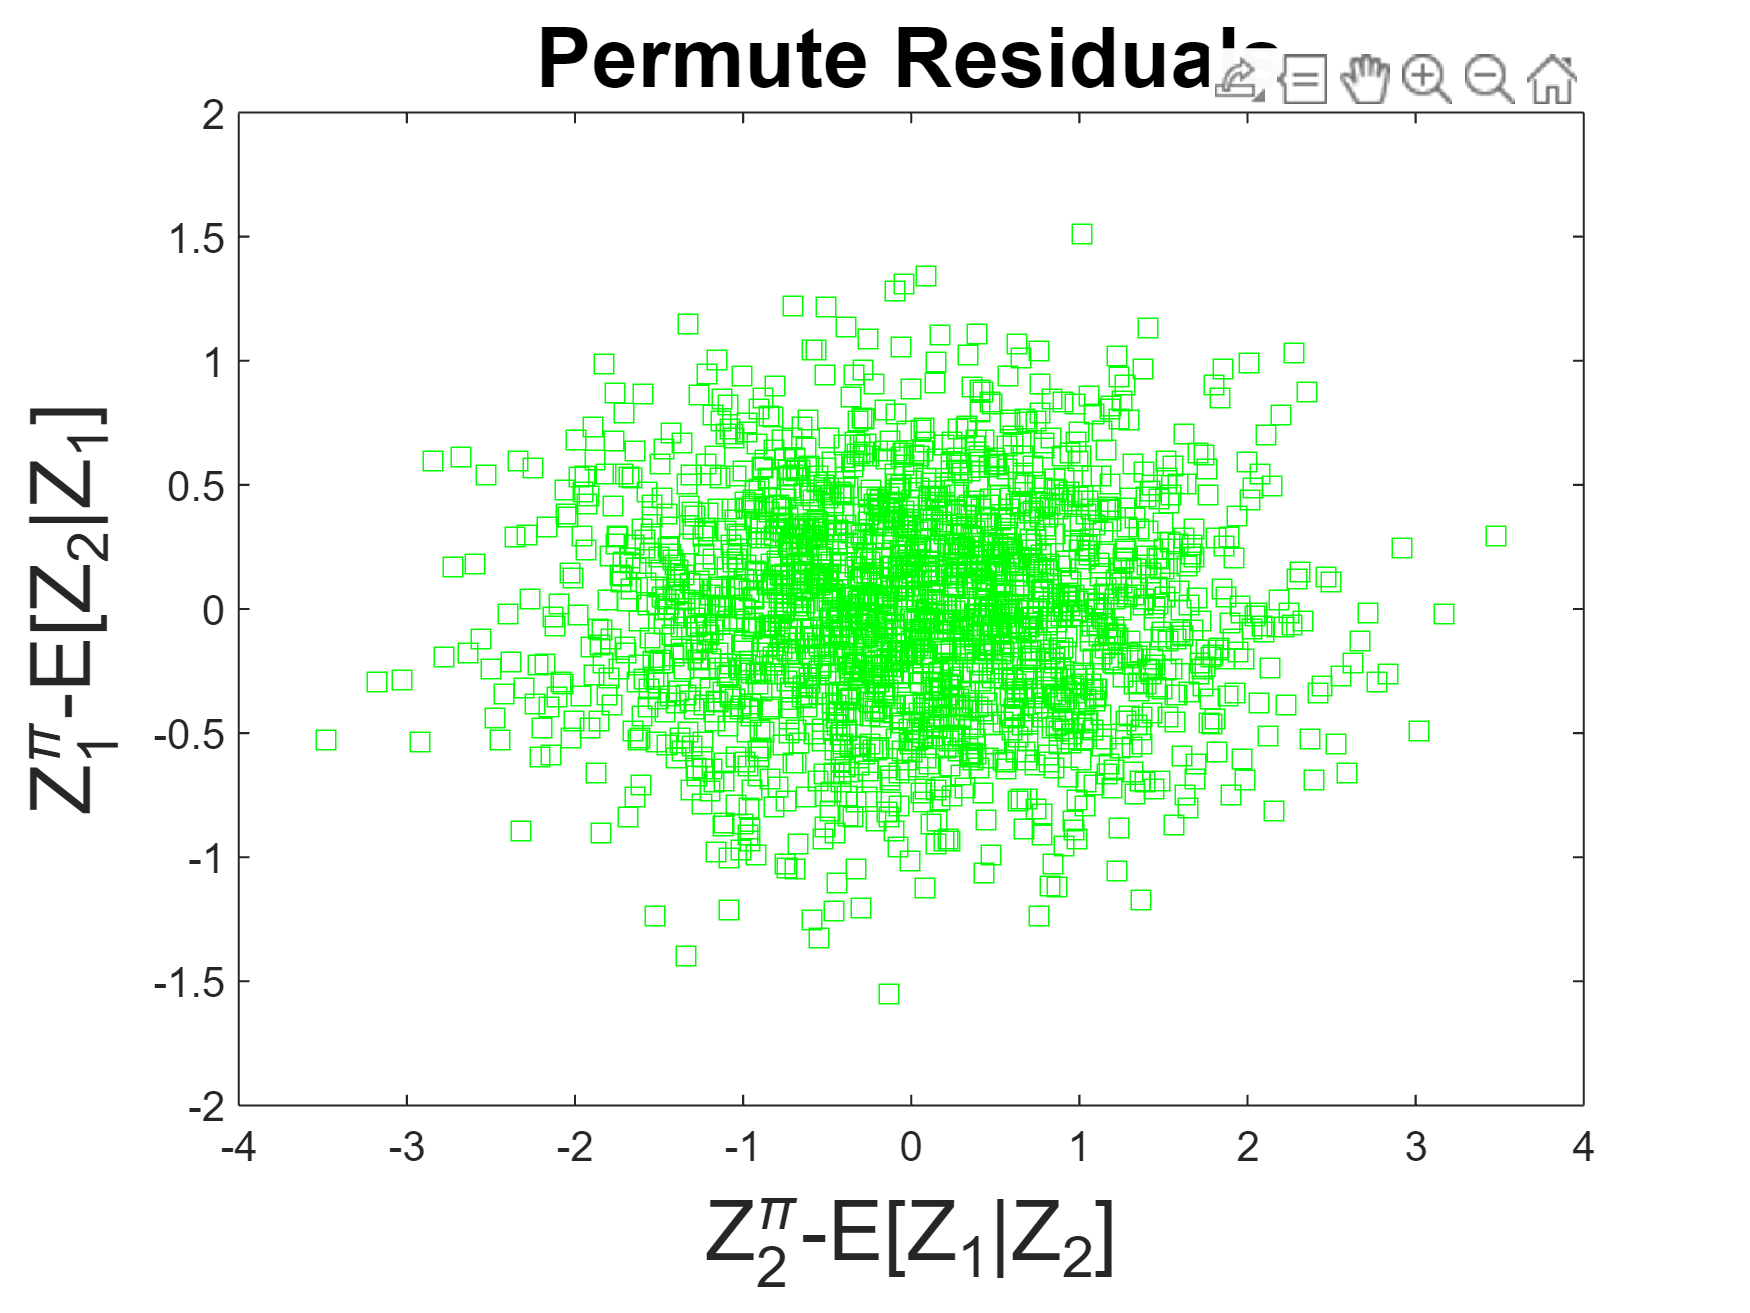

%subplot(4,1,3)
figure
plot(z(:,1),m,'gs')
title('Permute Residuals','FontSize',20);
xlabel('Z^{\pi}_{2}-E[Z_{1}|Z_{2}]','FontSize',20)
ylabel('Z^{\pi}_{1}-E[Z_{2}|Z_{1}]','FontSize',20)

%subplot(4,1,4)

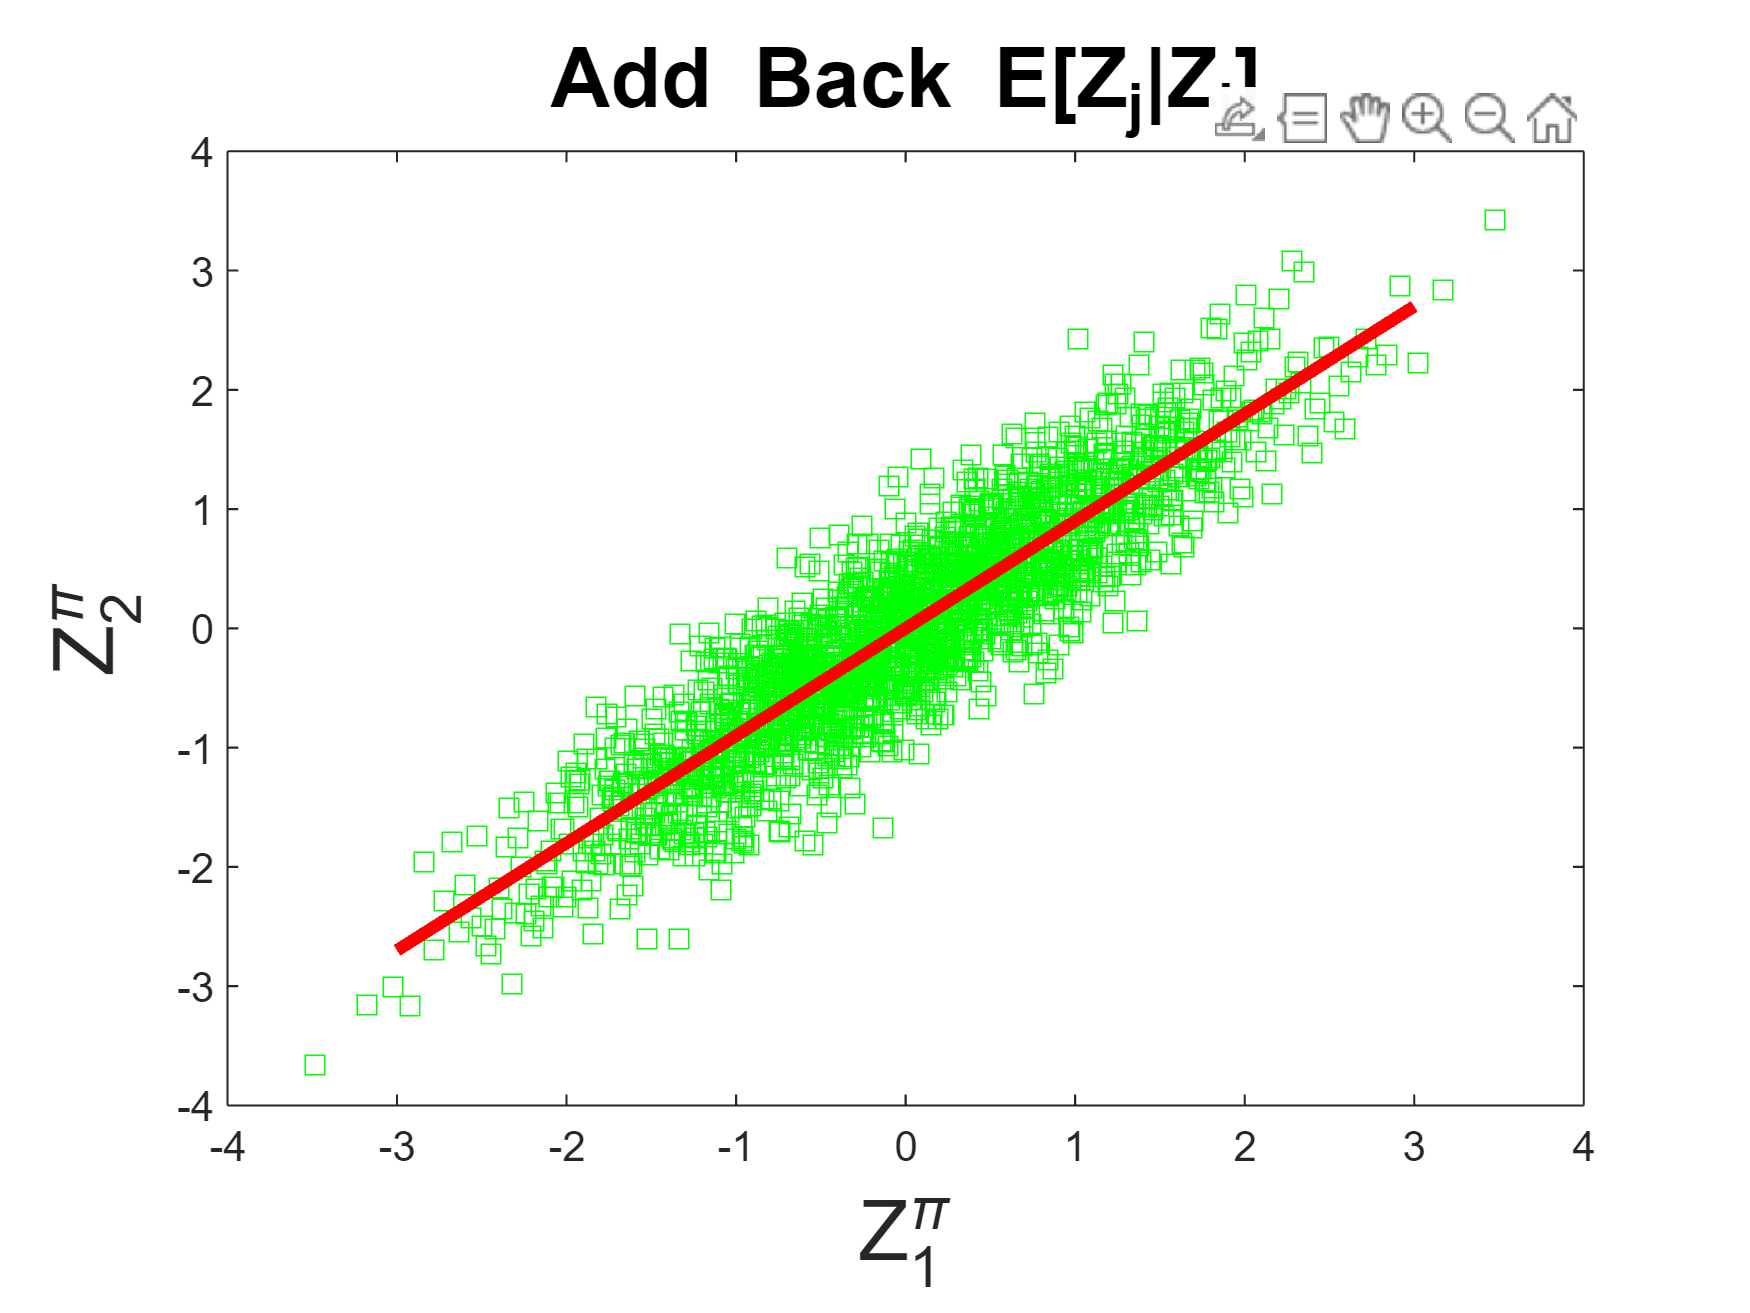

figure
zz=[z(:,1),.9*z(:,1)+m];
plot(zz(:,1),zz(:,2),'gs');hold on; plot([-3,3],.9*[-3,3],'r-','LineWidth',3)
title('Add Back E[Z_{j}|Z_{i}]','FontSize',20);
xlabel('Z_1^{\pi}','FontSize',20)
ylabel('Z_2^{\pi}','FontSize',20)

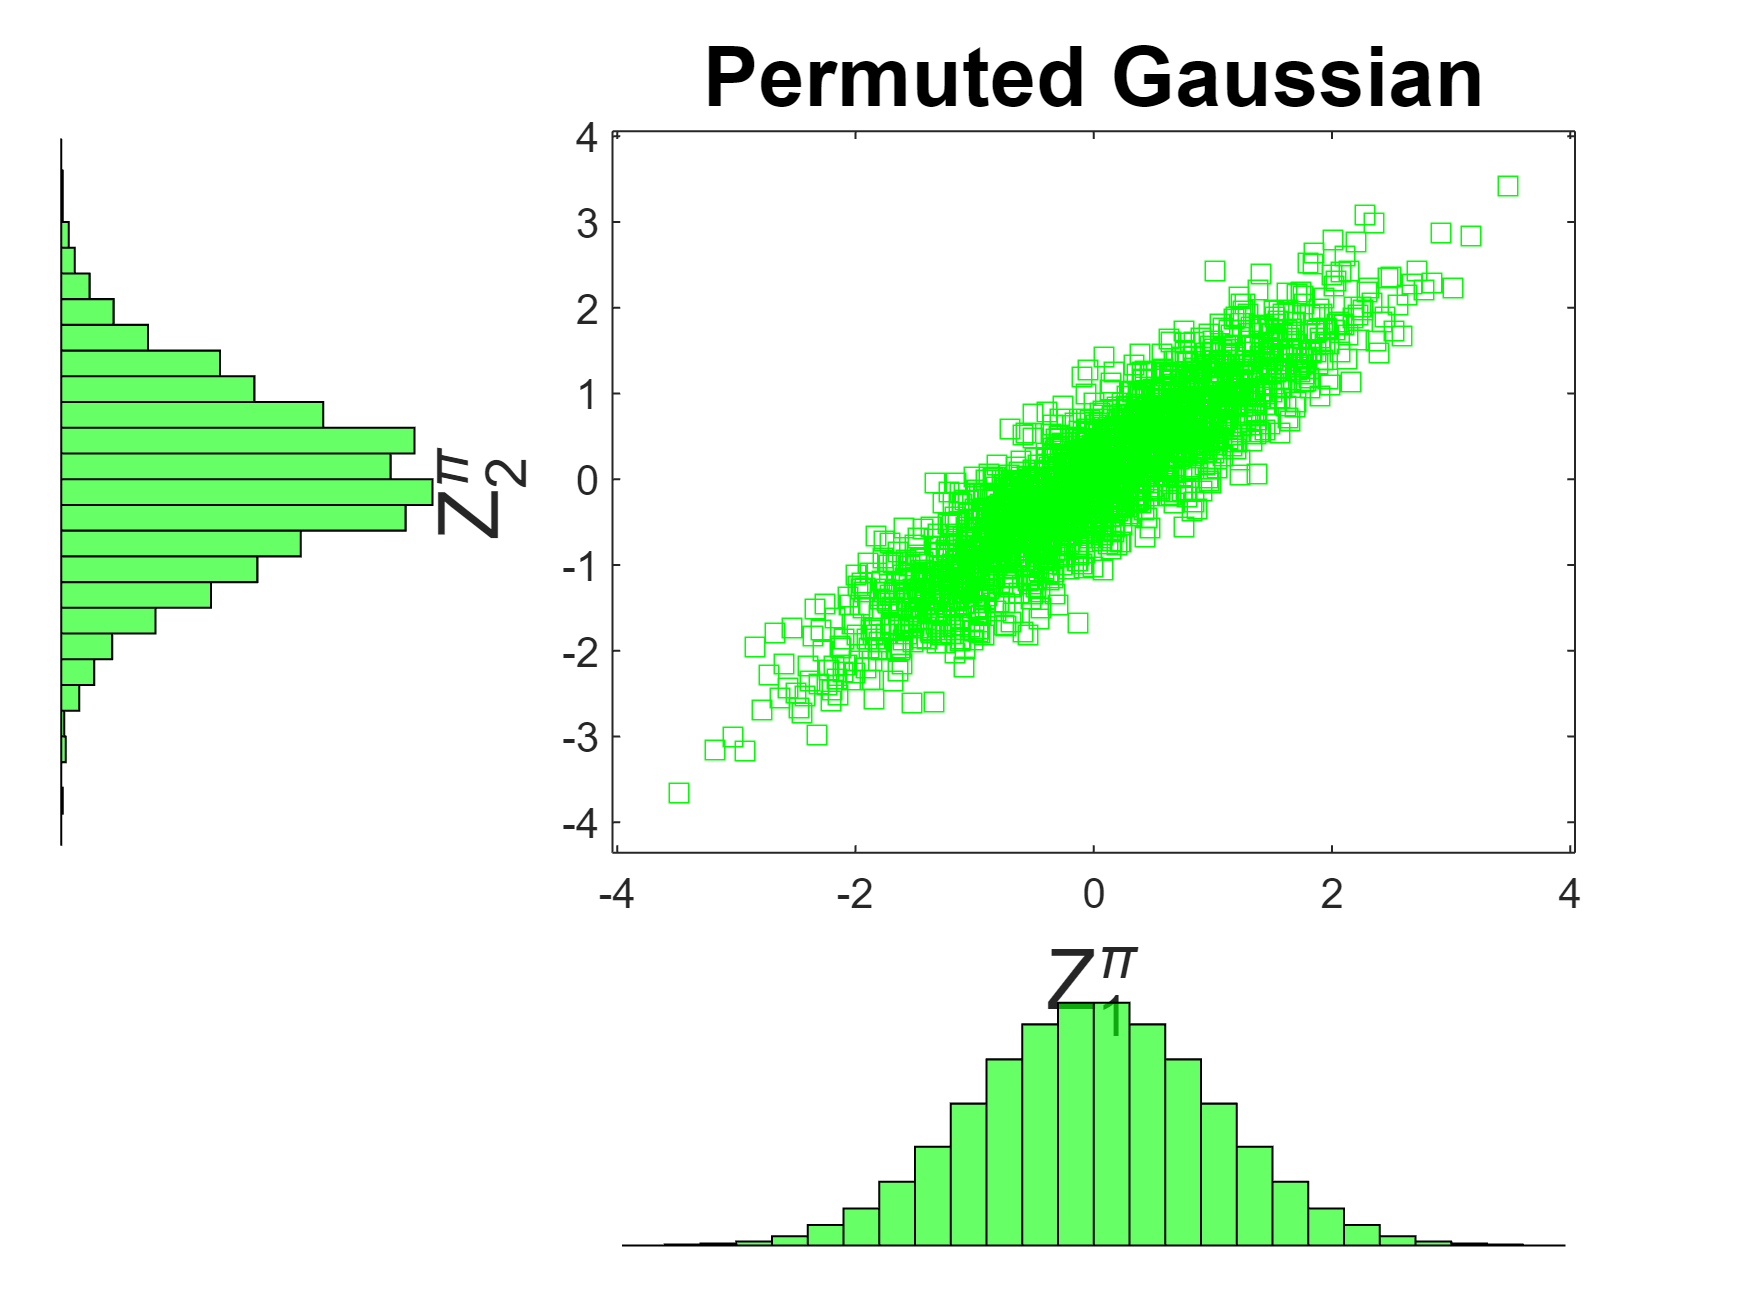

%% Still Gaussian
scatterhist(zz(:,1),zz(:,2),'Color','g','Marker','s');
title('Permuted Gaussian','FontSize',20);
xlabel('Z_1^{\pi}','FontSize',20)
ylabel('Z_2^{\pi}','FontSize',20)

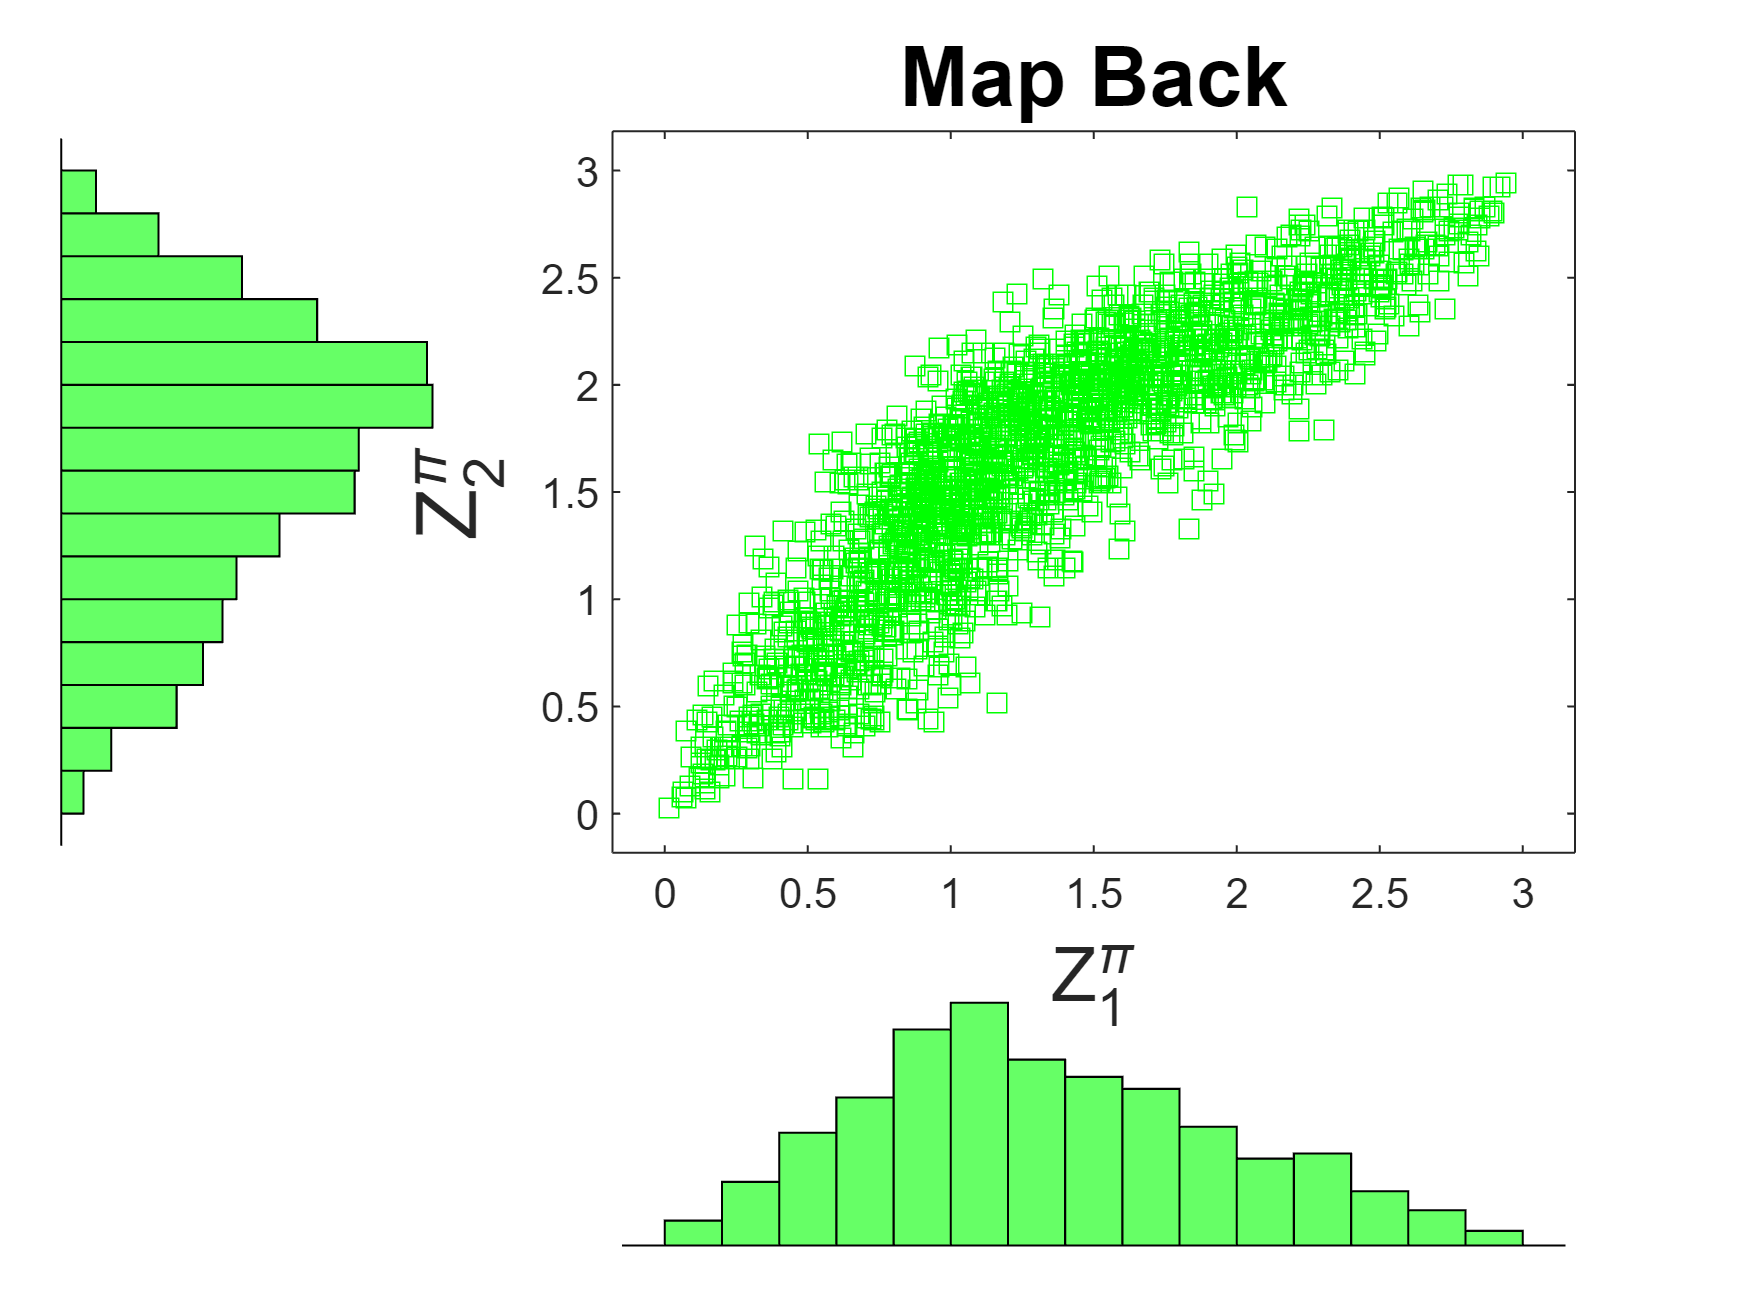



%% Back to Original Distribution
xs=sort(x(:,2));
%scatterhist(x(:,1),xs(ceil(normcdf(zz(:,2))*length(x))),'Color','g') %wo interpolation
%pause
xx=[x(:,1),quantile(x(:,2),normcdf(zz(:,2)))];
scatterhist(x(:,1),xx(:,2),'Color','g','Marker','s') % with
title('Map Back','FontSize',20);
xlabel('Z_1^{\pi}','FontSize',18)
ylabel('Z_2^{\pi}','FontSize',20)

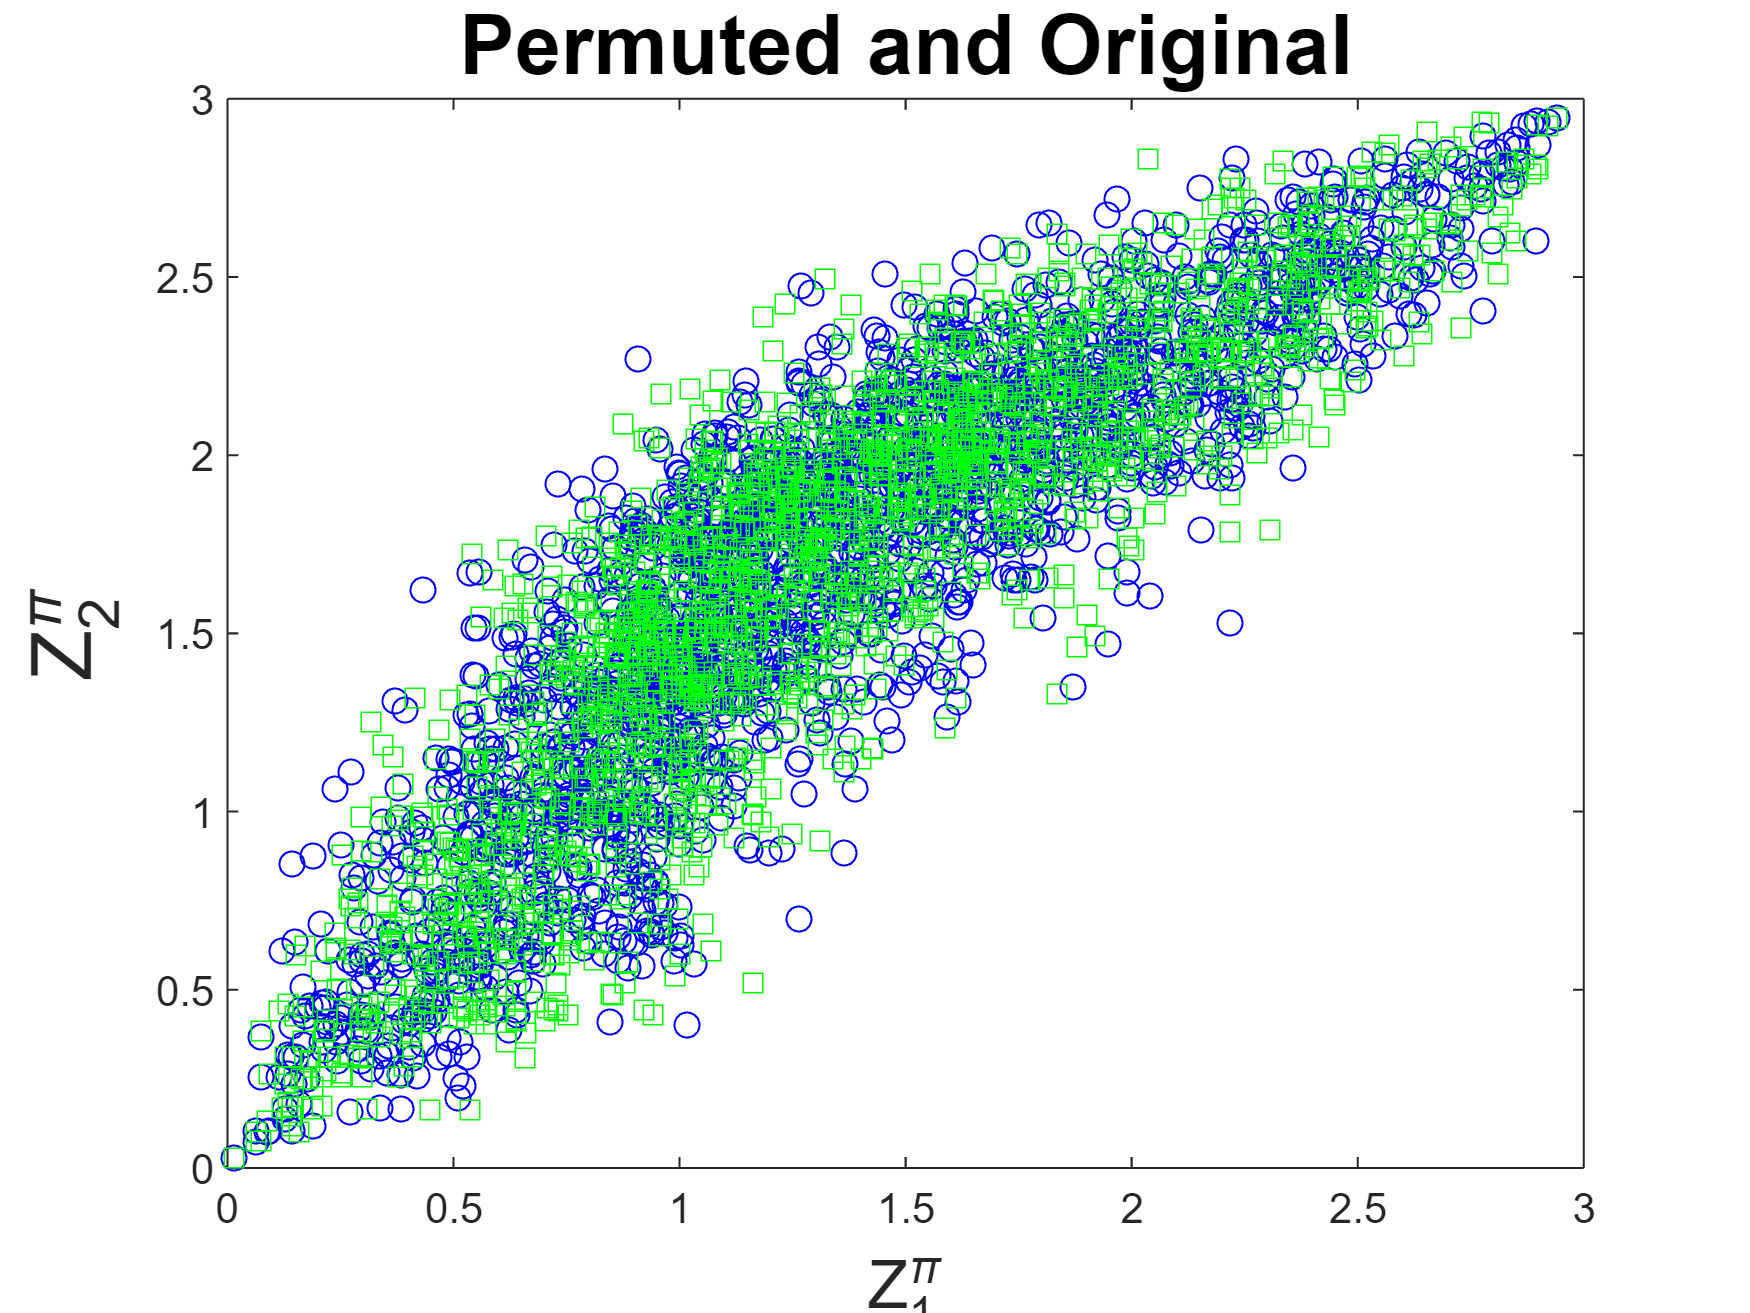



plot(x(:,1),x(:,2),'bo',xx(:,1),xx(:,2),'gs')
title('Permuted and Original','FontSize',20);
xlabel('Z_1^{\pi}','FontSize',16)
ylabel('Z_2^{\pi}','FontSize',20)